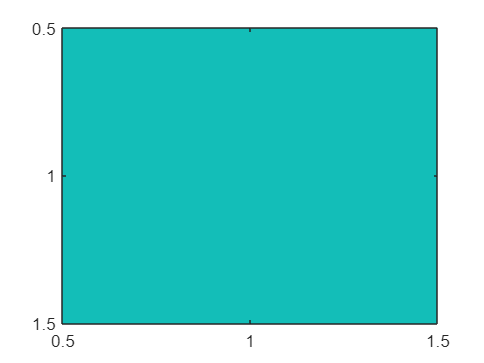

img = imread('squaredog.jpg');


R = img(:,:,1);
G = img(:,:,2);
B = img(:,:,3);


I = fft2(R);
mag = abs(I);
phs = angle(I);
%mag = flip(mag,2);
%mag = mag .* ((rand(size(mag)))+0.5);
% phs = atan(phs);
% phs = rescale(phs,-pi,pi);
% for i = 5: 631
%     for j = 5:631
%         x = randi([-4,4]);
%         y = randi([-4,4]);
%         mag(i,j) = mag(i+x,j+y);
%     end
% end
%mag = conv2(mag,ones([2,2])/2, 'same');
mag = max(max(mag))/1000;

I = mag.*exp(1i.*phs);
R = uint8(abs(ifft2(I)));

I = fft2(G);
mag = abs(I);
phs = angle(I);
%mag = flip(mag,2);
%mag = mag .* ((rand(size(mag)))+0.5);
% phs = atan(phs);
% phs = rescale(phs,-pi,pi);
% for i = 5: 631
%     for j = 5:631
%         x = randi([-4,4]);
%         y = randi([-4,4]);
%         mag(i,j) = mag(i+x,j+y);
%     end
% end
% mag = conv2(mag,ones([2,2])/2, 'same');
mag = max(max(mag))/1000;

I = mag.*exp(1i.*phs);
G = uint8(abs(ifft2(I)));

I = fft2(B);
mag = abs(I);
phs = angle(I);
%mag = flip(mag,2);
%mag = mag .* ((rand(size(mag)))+0.5);
% phs = atan(phs);
% phs = rescale(phs,-pi,pi);
% for i = 5: 631
%     for j = 5:631
%         x = randi([-4,4]);
%         y = randi([-4,4]);
%         mag(i,j) = mag(i+x,j+y);
%     end
% end
%mag = conv2(mag,ones([2,2])/2, 'same');
mag = max(max(mag))/1000;

I = mag.*exp(1i.*phs);
B = uint8(abs(ifft2(I)));


imagesc(log(mag));

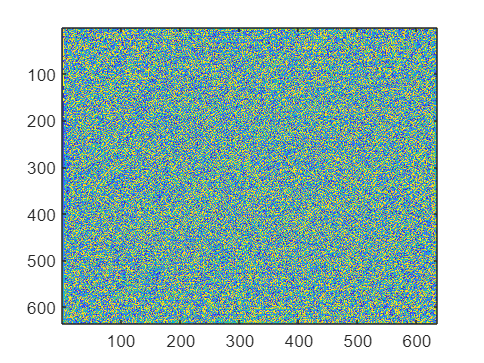

imagesc(phs);

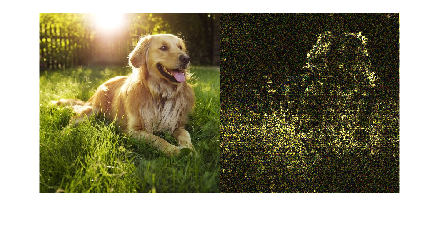


outImg = cat(3,R,G,B);
%outImg = uint8(abs(ifft2(outImg)));

toSave = montage({img,outImg});